## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Image Processing of Dermoscopic Images**

## MATLAB Project

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Methods**

Implement a classic image processing pipeline to classify each image, separating the two aforementioned types of cancer.

**1) Dataset:** Use imageDatastore and readall to import all the .jpg images from your working directory. Convert the images to grayscale and invert them.

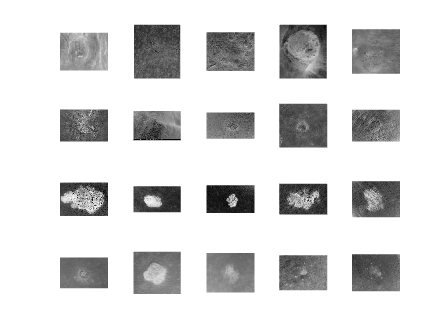

% We got this data from wikipedia,
% https://www.nhs.uk/conditions/actinic-keratoses/, 
% https://goldencoastdermatology.com/skin-cancer/actinic-keratosis/,
% https://www.merckmanuals.com/professional/dermatologic-disorders/reactions-to-sunlight/actinic-keratoses,
% https://www.silverbergmd.com/services/actinic-keratoses

% Define the folder path where the images are stored
folderPath = 'Validation';

% Create an imageDatastore object to read all the .jpg images from the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.jpg');

% Read all the images and convert them to grayscale and invert them
imds = readall(imds);
imds = cellfun(@(x) imcomplement(rgb2gray(x)), imds, 'UniformOutput', false);

% 'UniformOutput' is set to false to tell cellfun every output of the cell
% may not be uniform in size or shape (can have different data types)

% Display all inverted images in grayscale
figure;
for i = 1:numel(imds)
    subplot(4, 5, i);
    imshow(imds{i});
end

**2) Denoising:** Remove the noise of these images using a Gaussian filter.

% Define the standard deviation and filter size of the Gaussian filter
sigma = 1;
filterSize = 5;

% Apply a Gaussian filter to each image in the cell array
imds_filtered = cellfun(@(x) imgaussfilt(x, sigma, 'FilterSize', filterSize), imds, 'UniformOutput', false);

% Display all the denoised images in a loop
figure;
for i = 1:numel(imds_filtered)
    subplot(4, 5, i);
    imshow(imds{i});
end

**3) Thresholding:** Obtain binary masks using thresholding methods (e.g. Otsu) to separate the background (skin, black) from the foreground (lesion, white).

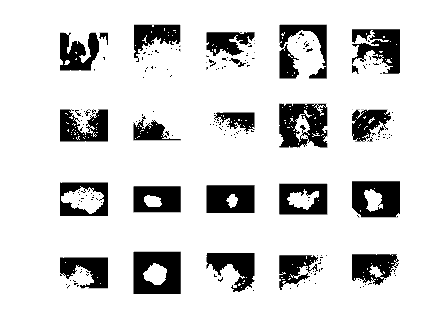

% Apply Otsu's method to each image to obtain threshold values
thresholds = cellfun(@(x) graythresh(x), imds_filtered);

% Apply the obtained threshold values to each image to obtain binary masks
imds_binary = cellfun(@(x, t) imbinarize(x, t), imds_filtered, num2cell(thresholds), 'UniformOutput', false);

%imshow(imds_binary{1})
% Display all the denoised images
figure;
for i = 1:numel(imds_binary)
    subplot(4, 5, i);
    imshow(imds_binary{i});
end

**4) Morphological Operations:** Clean the pre-processed masks by performing binary dilation, border clearing, small object removal and hole-filling within the lesion masks if needed.

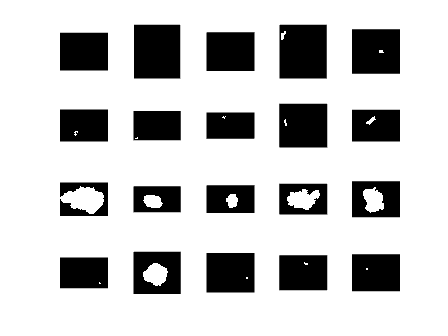

% Apply morphological operations to each binary mask
% disk-shaped structuring element with radius 3
se = strel('disk', 3);
for i = 1:numel(imds_binary)
    % Perform binary dilation 
    imds_binary{i} = imdilate(imds_binary{i}, se);
    
    % Perform border clearing
    imds_binary{i} = imclearborder(imds_binary{i});
    
    % Perform small object removal (<100 pixels)
    imds_binary{i} = bwareaopen(imds_binary{i}, 100);
    
    % Perform hole-filling
    imds_binary{i} = imfill(imds_binary{i}, 'holes');

    % Keep only largest connected component
    imds_binary{i} = bwareafilt(imds_binary{i}, 1);
end

% Show the cleaned and refined binary masks
figure;
for i = 1:numel(imds_binary)
    subplot(4, 5, i);
    imshow(imds_binary{i});
end

**5) Feature Extraction:** Multiply the grayscaled and inverted images from step 1) with the final binary masks obtained from step 4). Compute the standard deviation of the intensity distribution of each lesion and use regionprops to obtain the circularity of each mask.

% Loop through each image
for i = 1:numel(imds)
    
    % Multiply with binary mask
    imds_masked = double(cell2mat(imds(i))) .* double(cell2mat(imds_binary(i)));
    
    % Compute standard deviation of intensity distribution
    std_intensity(i) = std(double(imds_masked(:)));
    
    % Use regionprops to obtain circularity of mask
    stats = regionprops('table', imds_binary{i}, 'Circularity');
    %circularity(i) = stats.Circularity;
end

% Concatenate the features into a matrix and display it
features = [std_intensity', circularity'];

**6) Data Visualization and Analysis:** Perform k-means clustering to automatically separate the two classes (benign / malignant lesions). Use scatter to plot both features simultaneously in the 2D feature plane along with the corresponding estimated class label.

% Set the number of clusters (2 for benign/malignant)
k = 2;

% Perform k-means clustering on the features
[idx, centroids] = kmeans(features, k);

Error using kmeans
X must have more rows than the number of clusters.


% Plot the results
figure;
scatter(features(idx==1,1), features(idx==1,2), 40, 'filled', 'DisplayName','Malignant','MarkerFaceColor','r');
hold on;
scatter(features(idx==2,1), features(idx==2,2), 40, 'filled', 'DisplayName','Benign','MarkerFaceColor','#77AC30');
scatter(centroids(:,1), centroids(:,2), 150, 'x', 'Linewidth', 4, 'DisplayName','Centroids');
legend();
title('Malignant vs. Benign Lesions')
xlabel('Standard Deviation');
ylabel('Circularity');
% Display benign vs. malignant lesions
disp("Malignant:");disp("malignant"+(find(idx==2)-11));disp("Benign:");disp("benign"+(find(idx==1)-1));